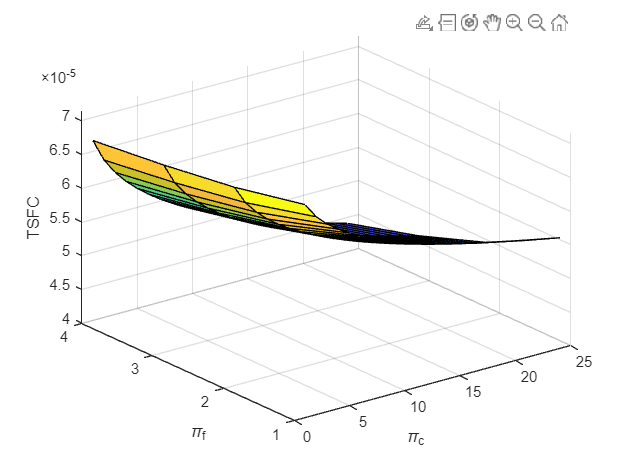

clc

%Problem 5
%Mixed Turbofan with afterburner

%Input parameters
M_a = 2.0;
P_a = 10000; %Static pressure(Pa)
T_a = 228.15; %Static temperature(K)
R = 287;
gamma = 1.4;
cp = 1004; %(J/kg.K)
%pi_c = 12; %(P_o3/P_o2) (To vary from 1 to 24)
%pi_f (P_o13/P_o2) To vary from 1 to 4
tow_lambda = 8; %((Cpt * T_o4)/(Cpc * T_a))
delH = 43 * 10^6; %Heating value (J/kg)
tow_lambda_AB = 11; %Temperature ratio of afterburner (T_o6/T_a)
P_oa = P_a * (1 + ((gamma-1)/2)*((M_a)^2))^((gamma)/(gamma-1));
T_oa = T_a * (1 + ((gamma-1)/2)*((M_a)^2));
pi_r = P_oa/P_a;
a_a = sqrt(gamma * R * T_a);
u_a = a_a * M_a;
%T_o4 = (tow_lambda)*T_a; %Burner exit temperature
%T_o6 = (tow_lambda_AB)*(T_oa); %Total temperature at exit of afterburner
alpha = 1.2;
pi_c = (1:1:24);
pi_f = (1:1:4);
mdotc = 74; %primary flow rate kg/s

for i = 1:1:4
    for j = 1:1:24
        %Fan
        P_o2(i,j) = pi_f(i)*P_oa;
        T_o2(i,j) = T_oa*((pi_f(i))^((gamma-1)/(gamma)));
        tow_f(i,j) = T_o2(i,j)/T_oa;
        %Compressor
        P_o3(i,j) = pi_c(j)*P_o2(i,j);
        T_o3(i,j) = T_o2(i,j)*(pi_c(j))^((gamma-1)/(gamma));
        %Burner
        P_o4(i,j) = P_o3(i,j);
        T_o4(i,j) = 8 * T_oa;
        tow_b(i,j) = T_o4(i,j)/T_o3(i,j);
        %Turbine
        T_o5(i,j) = T_o4(i,j) + T_o2(i,j) - T_o3(i,j) - alpha*(T_o2(i,j)-T_oa);
        P_o5(i,j) = P_o4(i,j) * (T_o5(i,j)/T_o4(i,j))^(gamma/(gamma-1));
        %Bypass Duct
        T_o7(i,j) = T_o2(i,j);
        P_o7(i,j) = P_o2(i,j);
        %Mixer
        T_o55(i,j) = T_oa*tow_f(i,j)*((alpha+tow_b(i,j)/(alpha+1)));
        P_o55(i,j) = P_o5(i,j);
        %Afterburner
        T_o6(i,j) = 11 * T_a;
        P_o6(i,j) = P_o55(i,j);
        %Nozzle
        M_8(i,j) = sqrt((2/(gamma-1))*(((P_o55(i,j)/P_a)^((gamma-1)/gamma))-1));
        T_8(i,j) = T_o6(i,j)/(1 + ((gamma-1)/2)*M_8(i,j)^2);
        u_8(i,j) = M_8(i,j)*sqrt(gamma*R*T_8(i,j));
        %Specific_thrust
        Specific_thrust(i,j) = (1+alpha)*(u_8(i,j) - u_a);
        %TSFC
        mdotf(i,j) = (mdotc * cp *(T_o4(i,j) - T_o3(i,j)))/(delH);
        mdotf_ab(i,j) = (1+alpha)*mdotc*cp*(T_o4(i,j) - T_o3(i,j))/(delH);
        mdot_tot(i,j) = mdotf(i,j) + mdotf_ab(i,j);
        TSFC = mdot_tot/(Specific_thrust(i,j) * mdotc);
        %Thermal efficiency
        Thermal_eff(i,j) = (Specific_thrust(i,j)*mdotc*u_a)/(mdot_tot(i,j)*delH);
        %Propulsive efficiency
        Prop_eff(i,j) = 2*u_a/(u_a + u_8(i,j));
        %Overall efficiency
        Overall_eff(i,j) = Thermal_eff(i,j)*Prop_eff(i,j);
    end
end

surf(TSFC)
xlabel('\pi_c')
ylabel('\pi_f')
zlabel('TSFC')
grid on

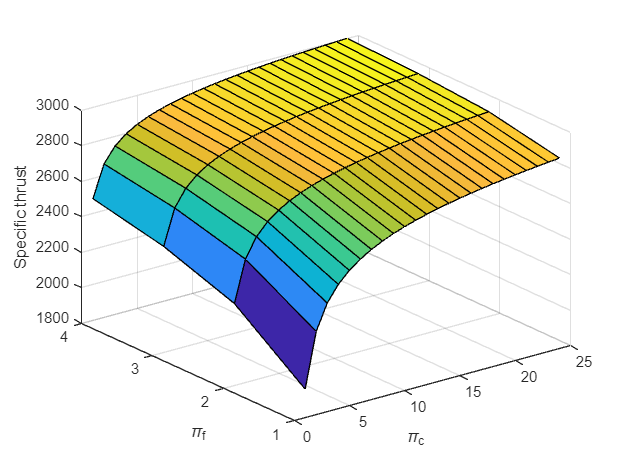


surf(Specific_thrust)
xlabel('\pi_c')
ylabel('\pi_f')
zlabel('Specific thrust')
grid on

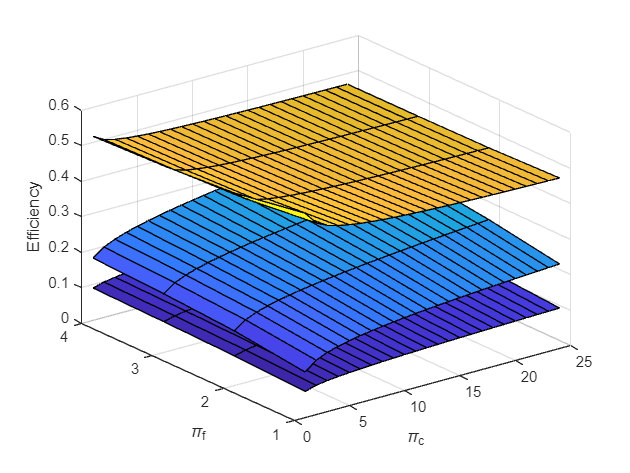


surf(pi_c,pi_f, Prop_eff)
hold on
surf(pi_c,pi_f, Thermal_eff)
hold on
surf(pi_c,pi_f, Overall_eff)
xlabel('\pi_c')
ylabel('\pi_f')
zlabel('Efficiency')
%zlabel('propulsive efficiency')
grid on


%{
xlabel('\pi_c')
ylabel('\pi_f')
zlabel('Thermal efficiency')
grid on


xlabel('\pi_c')
ylabel('\pi_f')
zlabel('Overall efficiency')
grid on
%}